## E

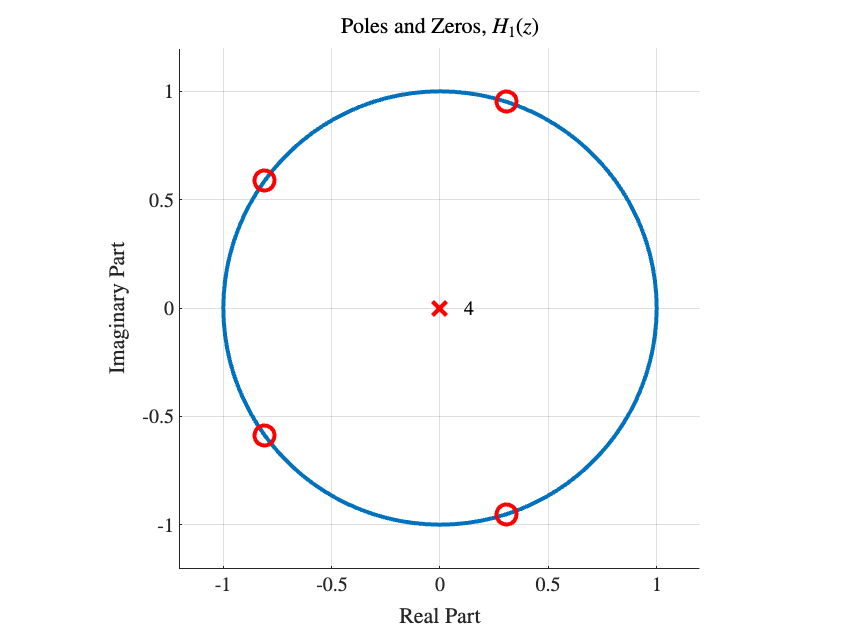

b = [1 1 1 1 1];
a = [1];
resolution = 1200;

figure()
hold on
plot(exp(1i*2*pi*(0:0.01:1)),'linewidth',2)
plot(roots(fliplr(b)),'ro','linewidth',2,'markersize',10)
plot(0,0,'rx','linewidth',2,'markersize',10)
text(0.1,0.0,'4','fontsize',10)
grid on
axis('square')
axis([-1.2 1.2 -1.2 1.2])
title('Poles and Zeros, $H_1(z)$')
xlabel('Real Part')
ylabel('Imaginary Part')
hold off
% exportgraphics(gcf, 'TeX/images/1E.png', 'Resolution',resolution);

## G

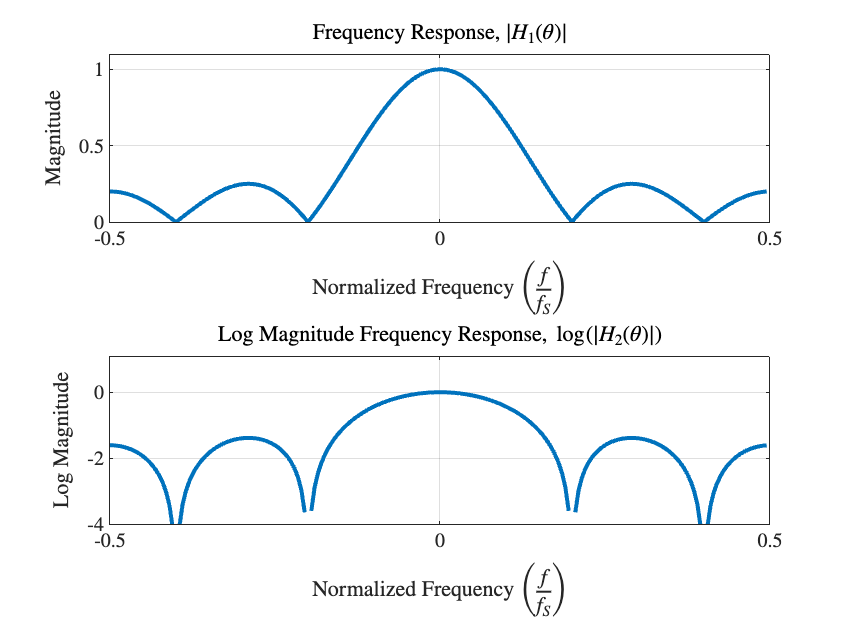

[H,W]=freqz(b,a,200,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/200:0.5-1/200);
subplot(2,1,1);
plot(frq,fftshift(abs(H))/max(abs(H)),'linewidth',2)
grid on
axis([-0.5 0.5 0 1.1])
title('Frequency Response, $|H_1(\theta)|$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Magnitude')

subplot(2,1,2);
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -4 1.1])
title('Log Magnitude Frequency Response, $\log(|H_2(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')


% exportgraphics(gcf, 'TeX/images/1G.png', 'Resolution',resolution);

## I

b = [1 -1 1 -1 1]

b =      1    -1     1    -1     1


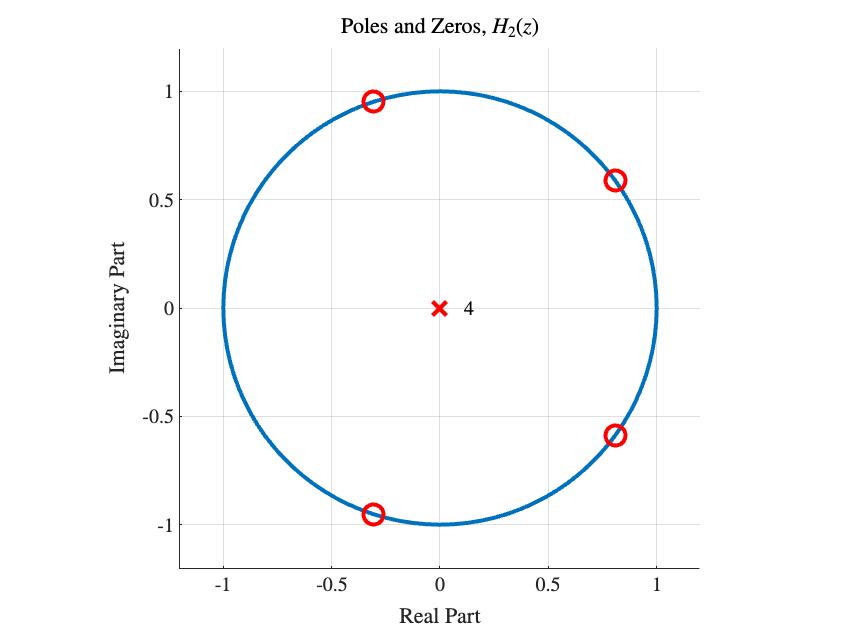

a = [1];

figure()
hold on
plot(exp(1i*2*pi*(0:0.01:1)),'linewidth',2)
plot(roots(fliplr(b)),'ro','linewidth',2,'markersize',10)
plot(0,0,'rx','linewidth',2,'markersize',10)
text(0.1,0.0,'4','fontsize',10)
grid on
axis('square')
axis([-1.2 1.2 -1.2 1.2])
title('Poles and Zeros, $H_2(z)$')
xlabel('Real Part')
ylabel('Imaginary Part')
hold off


% exportgraphics(gcf, 'TeX/images/1I.png', 'Resolution',resolution);

## K

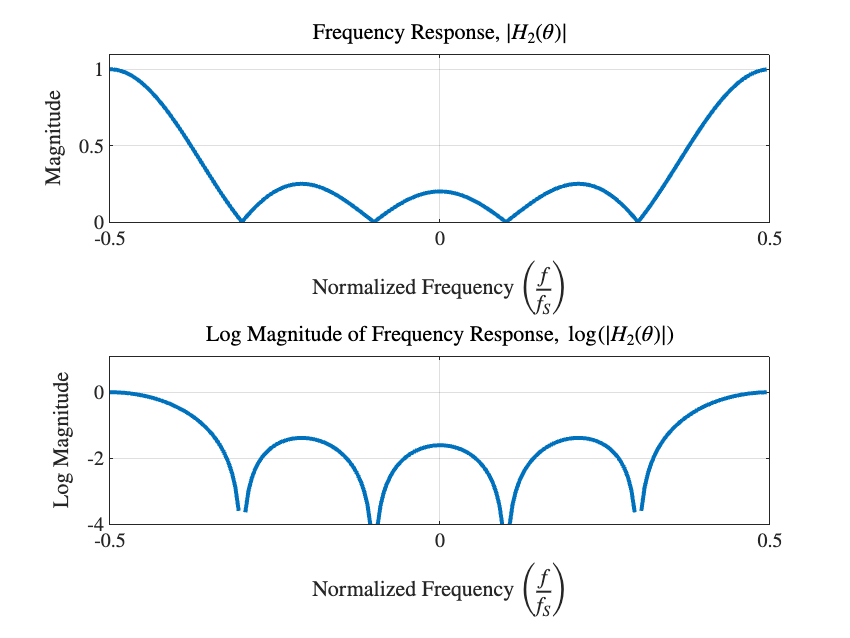

[H,W]=freqz(b,a,200,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/200:0.5-1/200);
subplot(2,1,1);
plot(frq,fftshift(abs(H))/max(abs(H)),'linewidth',2)
grid on
axis([-0.5 0.5 0 1.1])
title('Frequency Response, $|H_2(\theta)|$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Magnitude')

subplot(2,1,2);
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -4 1.1])
title('Log Magnitude of Frequency Response, $\log(|H_2(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')

% exportgraphics(gcf, 'TeX/images/1K.png', 'Resolution',resolution);